## SSIM Experiment

Po-Han Chen

**S**tructural **SIM**ularity (SSIM) index is an metric to evaluate the simularity between two images.

In this project, we explore how SSIM reacts to different distortion sources (noises, linear/non-linear transformations) and how it performs on different image domains (RGB, YUV, and gamma/degamma).

### Setup

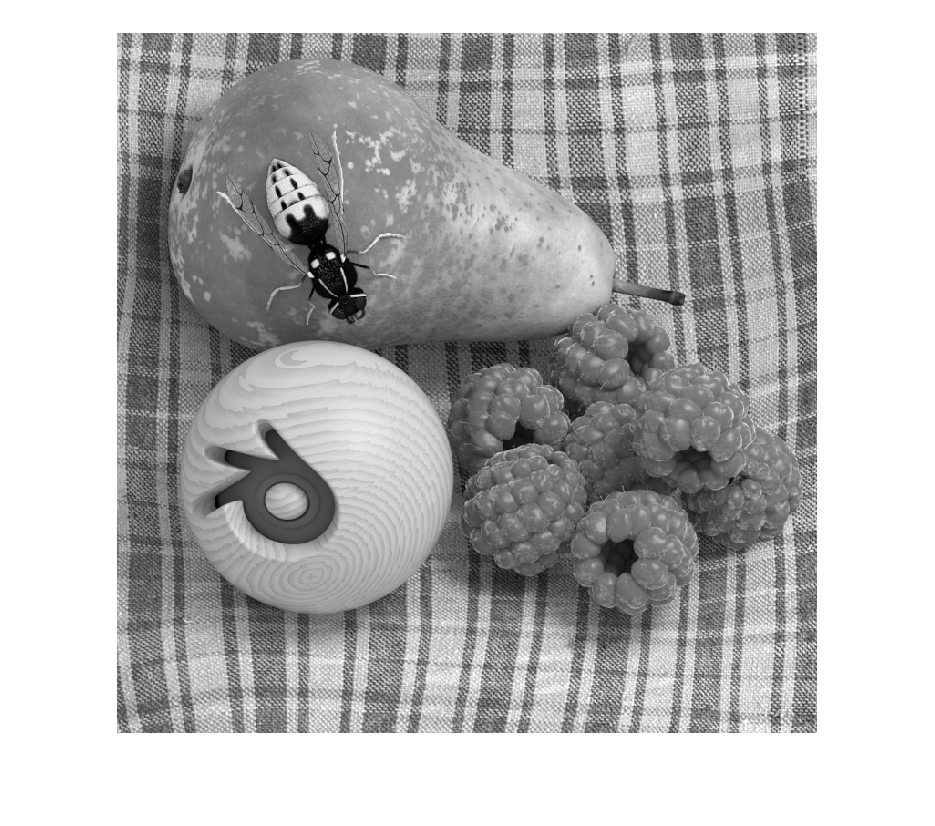

select = 6;
img_dir = "./img/";
benchmarks = [
    "dragonfly car/";  % 1
    "horses/";         % 2
    "lego_original/";  % 3
    "lytro_camera/";   % 4
    "pigeon/";         % 5
    "stilllife/";      % 6
    "truck_original/"; % 7
    "tsukuba/"         % 8
];
img_file = img_dir + benchmarks(select) + "02_02.png";
img_ref = rgb2gray(imread(img_file)); % SSIM is designed to work on gray images
imshow(img_ref);

### Basics

show how SSIM is computed:

### Distortion Sources (Noise Type)

Distortion can come from different sources. In this section, we discuss how different type of distortion sources affect the SSIM.

#### Noise Types

increase noise intensity, see how SSIM behaves

compare different noises (gaussian, speckle, salt & pepper)

do gaussian/poisson/salt/speckle noise, find same SSIM, compare quality & MSE

% Find variance that achieve targert SSIM
target_ssim = 0.1;
target_thresh = 0.01;
max_attemp = 100;

Gaussian Noise

% gaussian
var_min = 0.0;
var_max = 100.0;
var = var_min;
img_dist = imnoise(img_ref, "gaussian", 0.0, var);
ssim_val = ssim(img_dist, img_ref);
diff = ssim_val-target_ssim;
attemp = 0;
while abs(diff) >= target_thresh && attemp < max_attemp
    attemp = attemp + 1;
    if diff > 0
        var_min = var;
        var = (var+var_max)/2;
    else
        var_max = var;
        var = (var+var_min)/2;
    end
    img_dist = imnoise(img_ref, "gaussian", 0.0, var);
    ssim_val = ssim(img_dist, img_ref);
    mse_val = immse(img_dist, img_ref);
    diff = ssim_val-target_ssim;
end
fprintf("[gaussian] var=%f, ssim=%f, mse=%f\n", var, ssim_val, mse_val);

[gaussian] var=0.146484, ssim=0.108736, mse=6062.643943


gaussian_var_max = var;
imwrite(img_dist, "gaussian_same_ssim.png");

Salt & Pepper Noise

% salt&pepper
var_min = 0.0;
var_max = 1.0;
var = var_min;
img_dist = imnoise(img_ref, "salt & pepper", var);
ssim_val = ssim(img_dist, img_ref);
diff = ssim_val-target_ssim;
attemp = 0;
while abs(diff) >= target_thresh && attemp < max_attemp
    attemp = attemp + 1;
    if diff > 0
        var_min = var;
        var = (var+var_max)/2;
    else
        var_max = var;
        var = (var+var_min)/2;
    end
    img_dist = imnoise(img_ref, "salt & pepper", var);
    ssim_val = ssim(img_dist, img_ref);
    mse_val = immse(img_dist, img_ref);
    diff = ssim_val-target_ssim;
end
fprintf("[salt&pepper] var=%f, ssim=%f, mse=%f\n", var, ssim_val, mse_val);

[salt&pepper] var=0.343750, ssim=0.100386, mse=6437.381548


salt_var_max = var;
imwrite(img_dist, "salt_same_ssim.png");

Speckle Noise

% speckle
var_min = 0.0;
var_max = 100.0;
var = var_min;
img_dist = imnoise(img_ref, "speckle", var);
ssim_val = ssim(img_dist, img_ref);
diff = ssim_val-target_ssim;
attemp = 0;
while abs(diff) >= target_thresh && attemp < max_attemp
    attemp = attemp + 1;
    if diff > 0
        var_min = var;
        var = (var+var_max)/2;
    else
        var_max = var;
        var = (var+var_min)/2;
    end
    img_dist = imnoise(img_ref, "speckle", var);
    ssim_val = ssim(img_dist, img_ref);
    mse_val = immse(img_dist, img_ref);
    diff = ssim_val-target_ssim;
end
fprintf("[speckle] var=%f, ssim=%f, mse=%f\n", var, ssim_val, mse_val);

[speckle] var=0.585938, ssim=0.092596, mse=7949.244066


speckle_var_max = var;
imwrite(img_dist, "speckle_same_ssim.png");

Plot the SSIM versus noise variance results

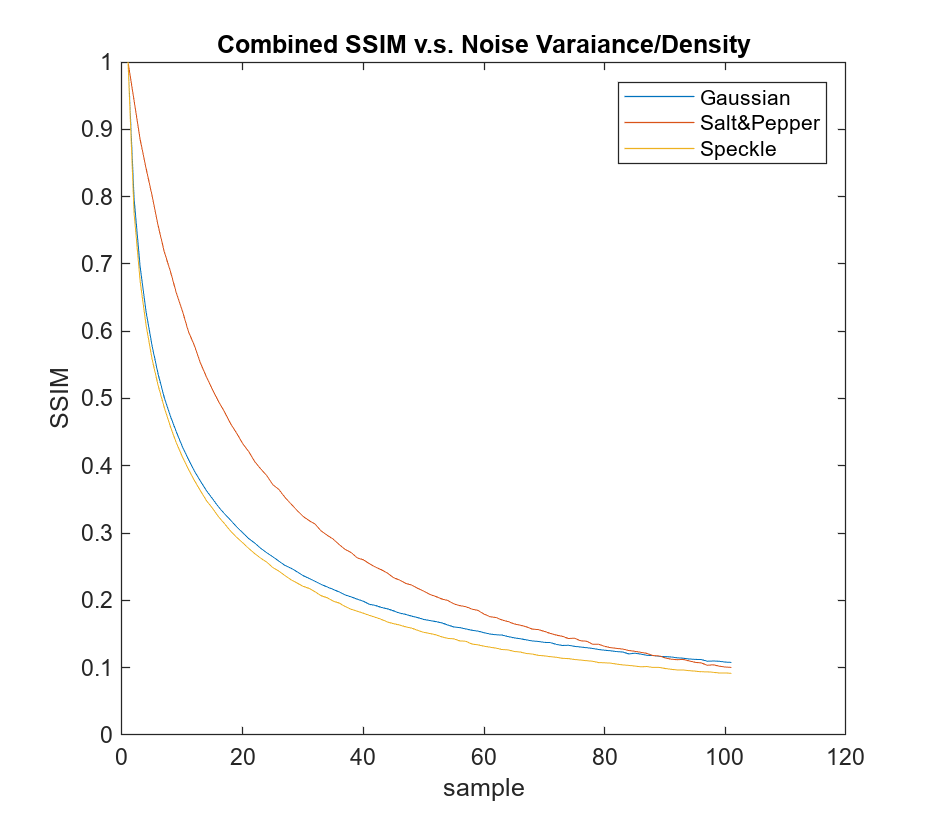

N = 100;
var_range_Gaussian = 0:(gaussian_var_max/(N)):gaussian_var_max;
var_range_SaltNPepper = 0:(salt_var_max/(N)):salt_var_max;
var_range_Speckle = 0:(speckle_var_max/(N)):speckle_var_max;

ssim_gaussian = zeros(size(var_range_Gaussian));
ssim_SaltNPepper = zeros(size(var_range_SaltNPepper));
ssim_Speckle = zeros(size(var_range_Speckle));

for i=1:(N+1)
    % gaussian
    img_dist = imnoise(img_ref, "gaussian", 0.0, var_range_Gaussian(i));
    ssim_gaussian(i) = ssim(img_dist, img_ref);
    % salt & pepper
    img_dist = imnoise(img_ref, "salt & pepper", var_range_SaltNPepper(i));
    ssim_SaltNPepper(i) = ssim(img_dist, img_ref);
    % speckle
    img_dist = imnoise(img_ref, "speckle", var_range_Speckle(i));
    ssim_Speckle(i) = ssim(img_dist, img_ref);
end

% plot(var_range_Gaussian, ssim_gaussian);
% xlabel('Variance'), ylabel('SSIM'), title('Gaussian Noise')
% plot(var_range_SaltNPepper, ssim_SaltNPepper);
% xlabel('Noise Density'), ylabel('SSIM'), title('Salt&Pepper Noise')
% plot(var_range_Speckle, ssim_Speckle);
% xlabel('Variance'), ylabel('SSIM'), title('Speckle Noise')

plot(1:(N+1), ssim_gaussian)
hold on
plot(1:(N+1), ssim_SaltNPepper)
plot(1:(N+1), ssim_Speckle)
xlabel('sample')
ylabel('SSIM')
title('Combined SSIM v.s. Noise Varaiance/Density')
legend('Gaussian', 'Salt&Pepper', 'Speckle')
hold off

### Distortion Sources (Image Transformation)

Explore how image transformation (translation, rotation, scaling) affect SSIM

#### Translation

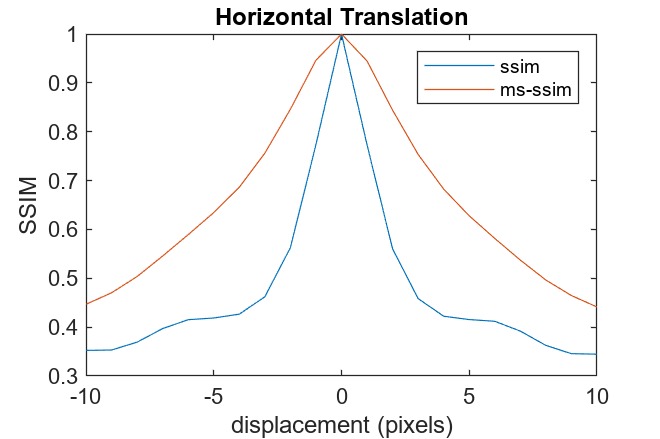

% bounding box
box_x = 200;
box_y = 200;
box_width = 400;
box_height = 300;

% translation amount
translation_x = 0;
translation_y = 0;

% reference image
img_ref_crop = img_ref(box_y:box_y+box_height, box_x:box_x+box_width); 

% distored (translated image)
box_tx = box_x + translation_x;
box_ty = box_y + translation_y;
img_dist = img_ref(box_ty:box_ty+box_height, box_tx:box_tx+box_width);

% subplot(1,2,1);
% imshow(img_ref_crop);
% subplot(1,2,2)
% imshow(img_dist);
ssim_val = multissim(img_dist, img_ref_crop);
% x translation
t_range = -10:10;
tx_ssim = zeros(size(t_range));
tx_mssim = zeros(size(t_range));
for i=1:numel(t_range)
    tx = t_range(i);
    box_tx = box_x + tx;
    box_ty = box_y;
    img_dist = img_ref(box_ty:box_ty+box_height, box_tx:box_tx+box_width);
    tx_ssim(i) = ssim(img_dist, img_ref_crop);
    tx_mssim(i) = multissim(img_dist, img_ref_crop);
end
box_tx = box_x + 1;
box_ty = box_y;
img_dist = img_ref(box_ty:box_ty+box_height, box_tx:box_tx+box_width);
imwrite(img_dist, "tx_1p.png");
imwrite(img_ref_crop, "ref_crop.png");
% y translation
t_range = -10:10;
ty_ssim = zeros(size(t_range));
ty_mssim = zeros(size(t_range));
for i=1:numel(t_range)
    ty = t_range(i);
    box_tx = box_x;
    box_ty = box_y + ty;
    img_dist = img_ref(box_ty:box_ty+box_height, box_tx:box_tx+box_width);
    ty_ssim(i) = ssim(img_dist, img_ref_crop);
    ty_mssim(i) = multissim(img_dist, img_ref_crop);
end
box_tx = box_x;
box_ty = box_y + 1;
img_dist = img_ref(box_ty:box_ty+box_height, box_tx:box_tx+box_width);
imwrite(img_dist, "ty_1p.png");

plot(t_range, tx_ssim)
hold on
plot(t_range, tx_mssim)
xlabel('displacement (pixels)'), ylabel('SSIM'), title('Horizontal Translation')
legend('ssim', 'ms-ssim')
hold off

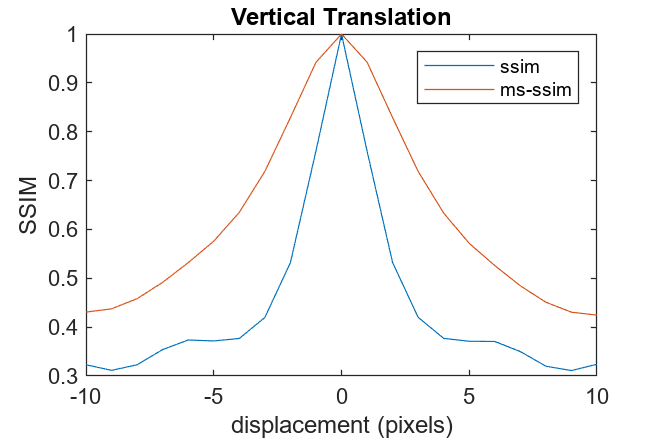

plot(t_range, ty_ssim);
hold on
plot(t_range, ty_mssim)
xlabel('displacement (pixels)'), ylabel('SSIM'), title('Vertical Translation')
legend('ssim', 'ms-ssim')
hold off

### Rotation

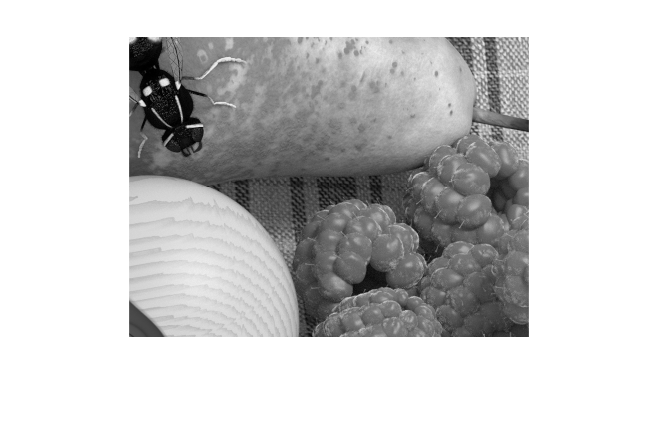

% bounding box
box_x = 200;
box_y = 200;
box_width = 400;
box_height = 300;

% reference image
img_ref_crop = img_ref(box_y:box_y+box_height, box_x:box_x+box_width);

% rotate
r_range = -45:45;
ssim_rot = zeros(size(r_range));
mssim_rot = zeros(size(r_range));
for i=1:numel(r_range)
    img_ref_rot = imrotate(img_ref, r_range(i), "bicubic", "crop");
    img_dist = img_ref_rot(box_y:box_y+box_height, box_x:box_x+box_width);
    ssim_rot(i) = ssim(img_dist, img_ref_crop);
    mssim_rot(i) = multissim(img_dist, img_ref_crop);
end

% show image
imshow(img_ref_crop);

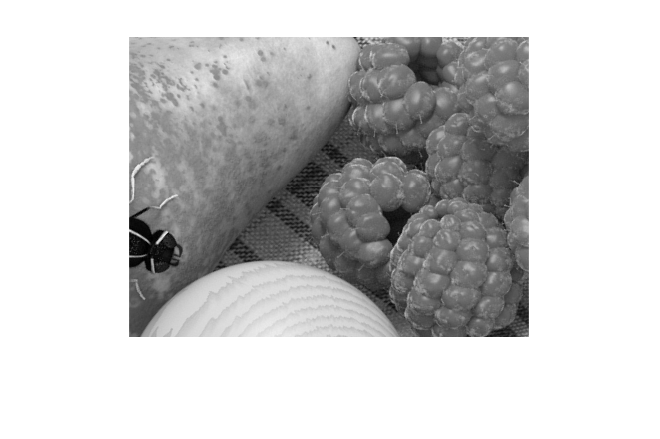

imshow(img_dist)

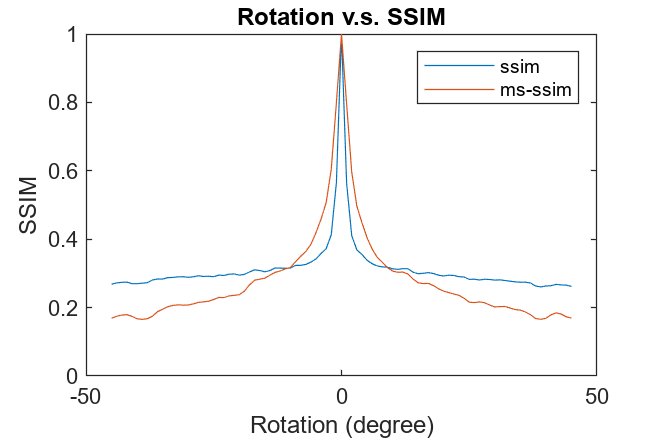

plot(r_range, ssim_rot);
xlabel('Rotation (degree)'), ylabel('SSIM'), title('Rotation v.s. SSIM')
hold on
plot(r_range, mssim_rot);
legend('ssim', 'ms-ssim')
hold off


img_ref_rot = imrotate(img_ref, 1, "bicubic", "crop");
img_dist = img_ref_rot(box_y:box_y+box_height, box_x:box_x+box_width);
imwrite(img_dist, "rot_d1.png");

### Scaling

% bounding box
box_x = 200;
box_y = 200;
box_width = 400;
box_height = 300;

% reference image
img_ref_crop = img_ref(box_y:box_y+box_height, box_x:box_x+box_width);

% scale
s_range = 0.9:0.01:1.1;
ssim_scale = zeros(size(s_range));
mssim_scale = zeros(size(s_range));
for i=1:numel(s_range)
    img_ref_scale = imresize(img_ref, s_range(i), "bilinear");
    box_xx = uint16(box_x*s_range(i)+box_width*(s_range(i)-1)/2);
    box_yy = uint16(box_y*s_range(i)+box_height*(s_range(i)-1)/2);
    img_dist = img_ref_scale(box_yy:box_yy+box_height, box_xx:box_xx+box_width);
    ssim_scale(i) = ssim(img_dist, img_ref_crop);
    mssim_scale(i) = multissim(img_dist, img_ref_crop);
end

% show image
imshow(img_ref_crop);

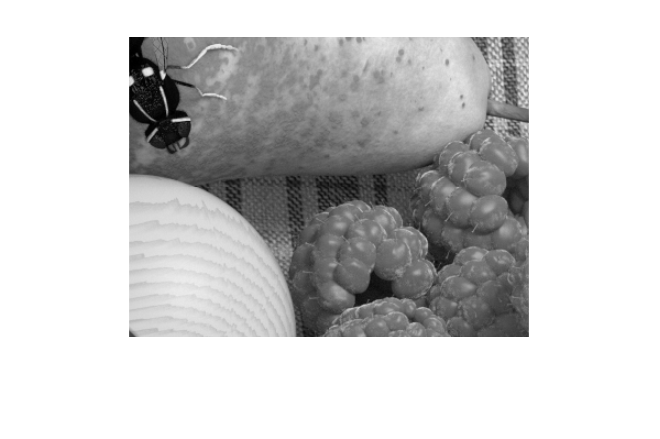

imshow(img_dist)

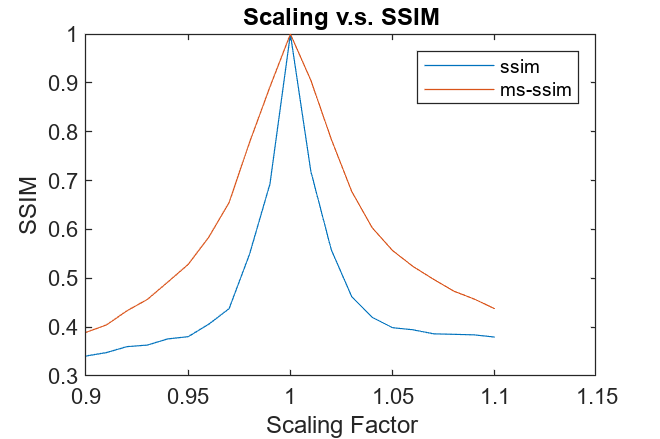

plot(s_range, ssim_scale);
xlabel('Scaling Factor'), ylabel('SSIM'), title('Scaling v.s. SSIM')
hold on
plot(s_range, mssim_scale);
legend('ssim', 'ms-ssim')
hold off


s=1.01;
img_ref_scale = imresize(img_ref, s, "bilinear");
box_xx = uint16(box_x*s+box_height*(s-1)/2);
box_yy = uint16(box_y*s+box_height*(s-1)/2);
img_dist = img_ref_scale(box_yy:box_yy+box_height, box_xx:box_xx+box_width);
imwrite(img_dist, "scale_d1.png");

#### Noise Band

apply same amount of noise at different frequency bands, see how it performs

#### Transformation

translation, rotation, scaling, different perspectives (light field)

### Image Domains